**Reset all:**

clc;
close all;
clear;

%To run the script, please open the HMI file first. This will open the GUI.

%Declare fixed variables
       
Lb = 0.0065;            %K/m
hb = 0;
g = 9.80665;
Mol = 0.0289644;
R1 = 8.3144598;
R = 287.5;

%Variables to be changed
T0 = 0;        %K
P0 = 0;        %
T1 = 0;
P1 = 0;
W1 = 0;
T2 = 0;
P2 = 0;
W2 = 0;
T21 = 0;
P21 = 0;
W21 = 0;
T3 = 0;
P3 = 0;
W3 = 0;
T31 = 0;
P31 = 0;
W31 = 0;
P4 = 0;
Q = 0;
W4 = 0;
WHPC = 0;
T41 = 0;
P41 = 0;
W41 = 0;
WLPC = 0;
T415 = 0;
P415 = 0;
W415 = 0;
T5 = 0;
P5 = 0;
W5 = 0;
Ps = 0;
Ts = 0;
Vj = 0;
rho = 0;
An = 0;
Fn = 0;
SFC = 0;
ETATH = 0;

%Run the Simulink model (HMI)
sim('./HMI_V3.slx');

Program interruption (Ctrl-C) has been detected.


%Request the input variables
engine_Type = ans.typeOfEngine;         % 0=Single spool | 1=Double spool
turbo_Fan = ans.turboFan;               % 0=Yes | 1=No
bleed = ans.bleed;                      % 0=Yes | 1=No
poly_Isen = ans.polytropicIsentropic;   % Polytropic=0 | Isentropic=1

Height = ans.height;                            %Height in meters
M = ans.mach;                                   %Mach number
P3Q2_LPC = ans.PressureratioLPC;                %Pressure ratio low pressure compressor
P3Q2_HPC = ans.PressureratioHPC;                %Pressure ratio High pressure compressor
P_loss_Compressor = ans.pressureLossCompressor; %Pressure loss compressor
P_loss_Combuster = ans.pressureLossCombuster;   %Pressure loss combuster
W0 = ans.massFlow;                              %Mass flow ambient
LHV = ans.fuelCalorificValue;                   %fuelCalorificValue
y_t = ans.gammaTurbine;                         %Heat capacity(Gamma) ratio turbine
y_c = ans.gammaCompressor;                      %Heat capacity(Gamma) ratio compressor
Cp_hot = ans.CPTurbine;                         %Specific(CP) heat turbine
Cp_cold = ans.CPCompressor;                     %Specific(CP) heat compressor

ETHA_Comp = ans.Isentropiccompressor;           %Isentropic efficiency compressor
ETHA_Comb = ans.Isentropiccombuster;            %Isentropic efficiency combuster
ETHA_turb = ans.Isentropicturbine;              %Isentropic efficiency turbine
ETHA_Comp_Poly = ans.Polytropiccompressor;
ETHA_Comb_Poly = ans.Polytropiccombuster;
ETHA_turb_Poly = ans.Polytropicturbine;
T4 = ans.Temperaturecombustion;                 %Temperature after combustion

Tb = ans.TemperatureAmbientAir + 273.16;        %Temperature ambien in Kelvin
Pb = ans.Pressureambientair;                    %

**Station 0: Atmospheric**

P0 = Pb * ((Tb - (Height - hb) * Lb)/Tb).^((g * Mol)/(R1 * Lb));    %Pressure Ambient
T0 = Tb - (Height * Lb);                                            %Temperature Ambient
W0 = W0;                                                            %Massflow Ambient

Functions

if poly_Isen == 0
    ETHA_Comb = (P3Q2_LPC^((y_c-1)/y_c)-1)/(P3Q2_LPC^((y_c-1)/(y_c*ETHA_Comp_Poly))-1);
    ETHA_Comp = (P3Q2_LPC^((y_c-1)/y_c)-1)/(P3Q2_LPC^((y_c-1)/(y_c*ETHA_Comb_Poly))-1);
    ETHA_Turb = (P3Q2_LPC^((y_t-1)/y_t)-1)/(P3Q2_LPC^((y_t-1)/(y_t*ETHA_turb_Poly))-1);
end
[T1, P1, W1] = Inlet(T0, P0, W0);
[T2, P2, W2] = LPC_Inlet(T1, P1, W1, y_c, M);
if engine_Type == 0
    [P3, T3, W3] = HPC(P2, T2, W2, P3Q2_HPC, y_c, ETHA_Comp);
else
    [P21, T21, W21] = LPC(T2, P2, W2, P3Q2_LPC, y_c, ETHA_Comp);
    [P3, T3, W3] = HPC(P21, T21, W21, P3Q2_HPC, y_c, ETHA_Comp);
end
[P31, T31, W31] = Combuster_Inlet(P3, T3, W3);
[P4, T4, W4, WF] = Combuster_Outlet(P31, T31, W31, T4, ETHA_Comb, Cp_hot, LHV);
[T41, P41, W41] = HPT_Inlet(P4, T4, W4, Cp_cold, Cp_hot, ETHA_turb, y_t, W3, T3, T21);
[T415, P415, W415] = LPT_Inlet(T41, W41, P41, Cp_cold, T21, T0, Cp_hot, ETHA_turb, y_t, W2, W4);
[T5, P5, W5] = LPT_Outlet(T415, P415, W415);
[Ps, Ts, Vj, rho, An, Fn, SFC, ETATH] = finalCalc(P5, T5, W0, WF, P0, LHV, y_c, R);
[aaa] = Image(engine_Type, Tb);
%[s1, s2, s3] = plot(h, SFC, Fn, ETATH)

%Send the output values 
sim('./HMI_V3.slx');

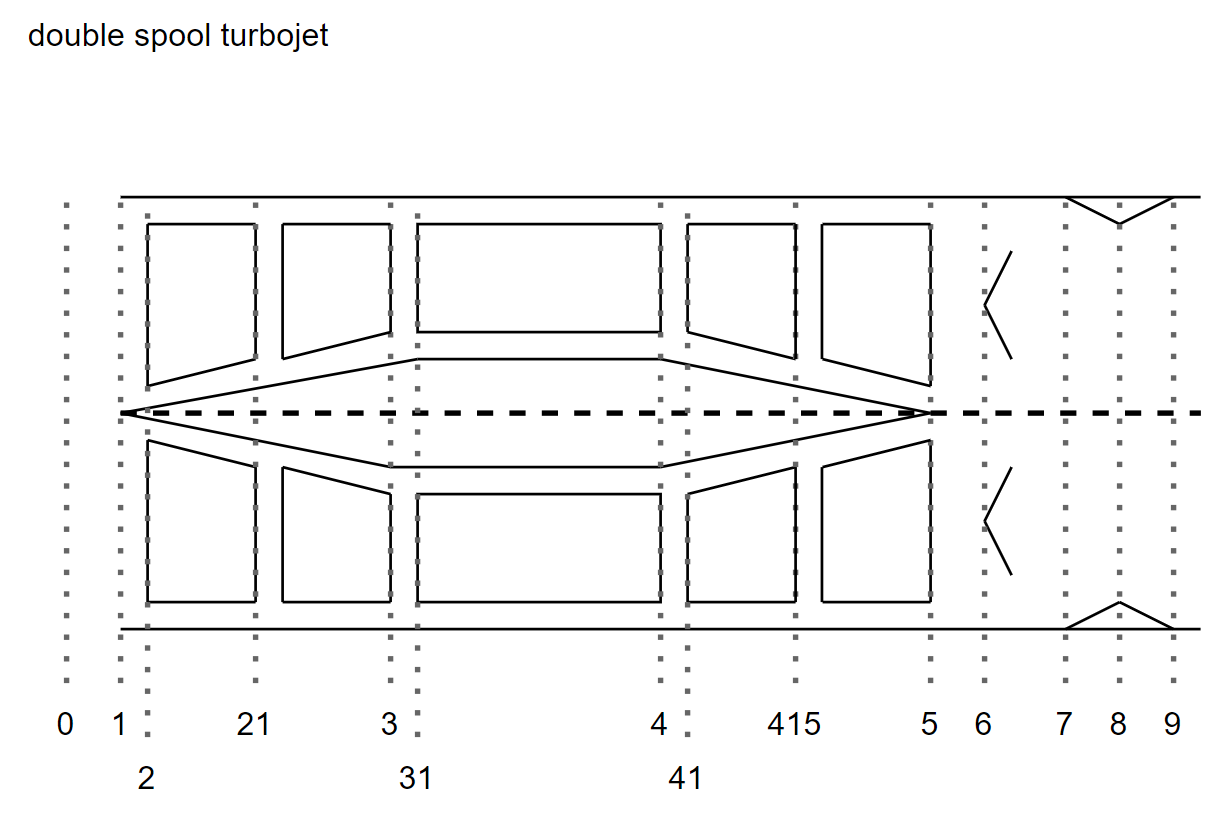

**Station 1: Inlet**

function [T1, P1, W1] = Inlet(T0, P0, W0)
    T1 = T0;
    P1 = P0;
    W1 = W0;
end

**Station 2: LPC (low pressure compressor) inlet**

function [T2, P2, W2] = LPC_Inlet(T1, P1, W1, y_c, M)
    T2 = T1 * (1 + ((y_c-1)/2) * M^2);
    P2 = P1 * (T2/T1)^(y_c/(y_c-1));
    W2 = W1;                            % Nothing is added to the flow
end

**Station 21: LPC**

function [P21, T21, W21] = LPC(T2, P2, W2, P3Q2_LPC, y_c, ETHA_Comp)
    P21 = P2 * P3Q2_LPC;
    T21 = T2 * (1 + ((P21/P2)^((y_c - 1)/y_c)- 1)/ETHA_Comp);
    W21 = W2;                           % Nothing is added to the flow
end

**Station 3: HPC (high pressure compressor) outlet**

function [P3, T3, W3] = HPC(P21, T21, W21, P3Q2_HPC, y_c, ETHA_Comp)
    P3 = P21 * P3Q2_HPC;
    T3 = T21 * (1 + ((P3/P21)^((y_c - 1)/y_c)- 1)/ETHA_Comp);
    W3 = W21;                           % Nothing is added to the flow
end

**Station 31 Combuster inlet**

function [P31, T31, W31] = Combuster_Inlet(P3, T3, W3)
    P31 = P3;
    T31 = T3;
    W31 = W3;
end

**Station 4: Combustor outlet**

function [P4, T4, W4, WF] = Combuster_Outlet(P31, T31, W31, T4, ETHA_Comb, Cp_hot, LHV)
    P4 = P31 * ETHA_Comb;
    Q = W31 * Cp_hot * (T4 - T31);
    WF = Q/LHV;
    W4 = WF + W31;
end

**Station 41: HPT (high pressure turbine) inlet**

function [T41, P41, W41] = HPT_Inlet(P4, T4, W4, Cp_cold, Cp_hot, ETHA_turb, y_t, W3, T3, T21)
    WHPC = W3 * Cp_cold * (T3 - T21);
    T41 = T4 - (WHPC./(W4.* Cp_hot));
    P41 = P4.* (1- (1-(T41./T3))/ETHA_turb).^(y_t/(y_t- 1));
    W41 = W4;                           % Nothing is added to the flow
end

**Station 415: LPT (low pressure turbine) inlet**

function [T415, P415, W415] = LPT_Inlet(T41, W41, P41, Cp_cold, T21, T0, Cp_hot, ETHA_turb, y_t, W2, W4)
    WLPC = W2 * Cp_cold * (T21 - T0);
    T415 = T41 - (WLPC./(W4.* Cp_hot));
    P415 = P41 * (1 - (1-(T415/T41))/ ETHA_turb)^(y_t/(y_t- 1));
    W415 = W41;                           % Nothing is added to the flow
end

**Station 5: LPT outlet **

function [T5, P5, W5] = LPT_Outlet(T415, P415, W415)
    T5 = T415;
    P5 = P415;
    W5 = W415;
end

**Final Calculations**

function [Ps, Ts, Vj, rho, An, Fn, SFC, ETATH] = finalCalc(P5, T5, W0, WF, P0, LHV, y_c, R)
    Ps = P5/(1 + (y_c - 1)/2)^(y_c/(y_c-1));
    Ts = T5/(1 + (y_c - 1)/2);
    Vj = sqrt(y_c * R *Ts);
    rho = (Ps.*1000)./(Ts.*R);
    An = W0./(Vj.*rho);
    Fn = (W0 + WF).* Vj + An.* (Ps - P0);
    SFC = (WF./Fn).* 1000000;
    ETATH = 100.*(3600./(SFC.*(LHV/10^5)));
end

**Generate images (Output , Input)**

function [aaa] = Image(engine_Type, Tb)
aaa = 1;

%Engine type view
if engine_Type == 0
    afbeelding = imread('C:\Users\martn\Desktop\SCHOOL HBO 2\Leerjaar4\Periode2\Afbeeldingen\Single_spool.png'); % Vervang 'pad_naar_jouw_afbeelding.jpg' door het werkelijke pad naar je afbeelding
    imshow(afbeelding);
end
if engine_Type == 1
    afbeelding = imread('C:\Users\martn\Desktop\SCHOOL HBO 2\Leerjaar4\Periode2\Afbeeldingen\Double_spool.png'); % Vervang 'pad_naar_jouw_afbeelding.jpg' door het werkelijke pad naar je afbeelding
    imshow(afbeelding);
end




end